A1 = [1, -0.8];
A2 = [1, 0.8];
n2 = 0 : 99;

a_x = [0, 0.75, zeros(1, 7), -0.5, zeros(1, 10)];
x_20 = ifft(a_x) * length(a_x);

x = [x_20, x_20, x_20, x_20, x_20];

y1 = filter(1, A1, x);
y2 = filter(1, A2, x);

subplot(2, 1, 1);
stem(n2, y1);

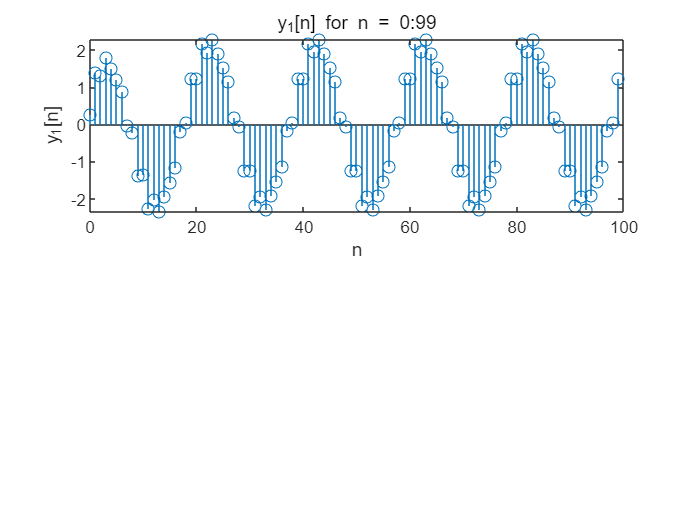

xlabel("n");
ylabel("y_1[n]");
title("y_1[n] for n = 0:99");

subplot(2, 1, 2);
stem(n2, y2);

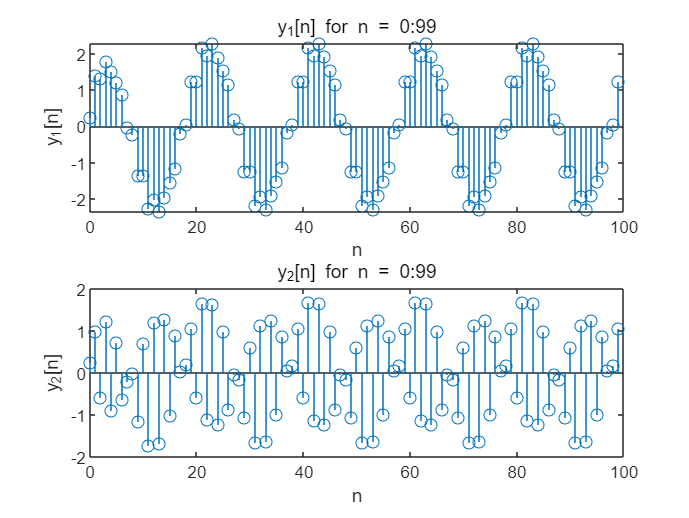

xlabel("n");
ylabel("y_2[n]");
title("y_2[n] for n = 0:99");